%Solution 1
syms s a0 a1 b0 b1 b2
expand( (s+4)^2 * (s+5)^2  )

$$ans = s^{4}+18\,s^{3}+121\,s^{2}+360\,s+400$$

expand( (s+4)*(s+2)*s*(a1*s+a0) + 3*(b2*s^2+b1*s+b0) )

$$ans = 3\,b_{0}+8\,a_{0}\,s+3\,b_{1}\,s+6\,a_{0}\,s^{2}+a_{0}\,s^{3}+8\,a_{1}\,s^{2}+6\,a_{1}\,s^{3}+a_{1}\,s^{4}+3\,b_{2}\,s^{2}$$


G = 3/((s+4)*(s+2));
C = (41*s^2 + 264*s + 400)/(3*s*(s+12))

$$C = \frac{41\,s^{2}+264\,s+400}{3\,s\,\left(s+12\right)}$$

P = G*C;
R = (1/s);
Y = (P/(1+P))*R;
y = ilaplace(Y)

$$y = 16\,{\mathrm{e}}^{-4\,t}-17\,{\mathrm{e}}^{-5\,t}-21\,t\,{\mathrm{e}}^{-5\,t}+1$$

c = ilaplace(C);

t = 5

t = 5

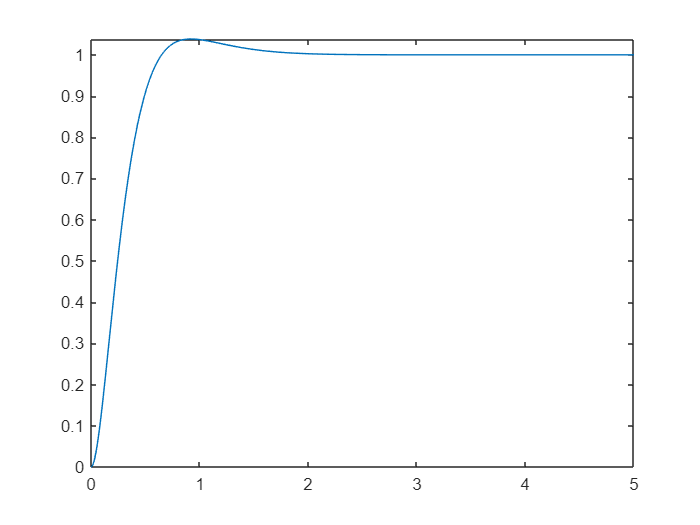

fplot(y,[0 t])

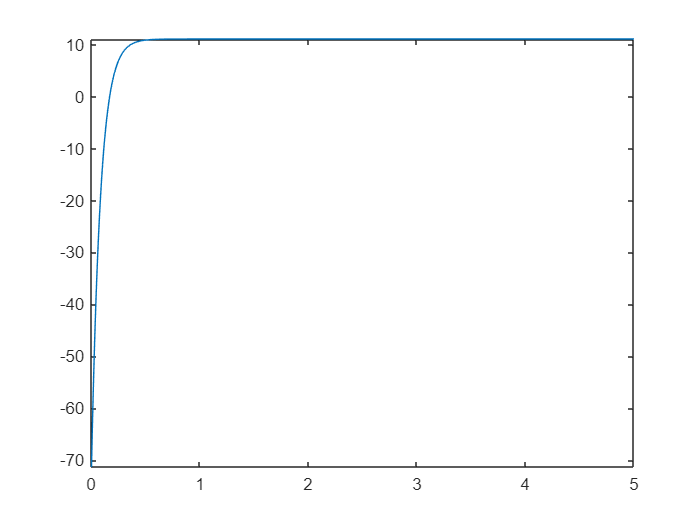

fplot(c,[0 t])

%Lecture example solution, pg 17
syms s
U = (8.33*s^2 + 205*s + 2054)/(s^3+116.5*s^2)
u = ilaplace(U)

t = 5
fplot(u,[0 t])